# WFS Prefilter Design

I want to design a filter with the response of the ideal half-differentiator

$H(f) = \sqrt{j\frac{f}{c}}$.

The ideal response is

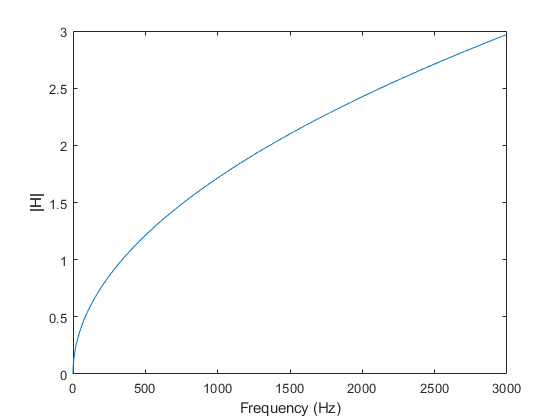

f = 0:3000;
c = 340;
H = sqrt(1i*f/c);
ax = axes(figure);
plot(ax, f, abs(H))
ax.XLabel.String = 'Frequency (Hz)';
ax.YLabel.String = '|H|';

## FIR design

To be completed

## IIR design

I want to test if I can get the prefilter by using IIR filters of low orders.

I got the idea from the paper *Derivation of IIR prefilters for soundfield synthesis using linear secondary source distributions* by Frank Schultz.

Very interesting resource in [Introduction to Digital Filters by JULIUS O. SMITH III](https://www.dsprelated.com/freebooks/filters/).

In the mentioned paper, the equation (3) will serve as starting point.


$$H = g_2 \frac{s\frac{\sqrt{g_1}}{\omega_c} + 1}{s\frac{1}{\omega_c\sqrt{g_1}} + 1}$$


The variable $s$ is the Laplace transform variable, and without getting into details that I don't fully understand, it has to be substituted by $s = j2\pi f$. The value of $H(f)$ at $f=0$ is $g_2$, and the value when $f$ tends to infinite is $g_1 g_2$. The phase is (after simple equation manipulation):


$$\phi = \arctan \frac{\frac{\omega}{\omega_c}(\sqrt{g_1} + \frac{1}{\sqrt{g_1}})}{1 + \frac{\omega}{\omega_c}^2}$$


It reaches its maximum at $2\pi f = \omega = \omega_c$ (making the first derivative equal to 0 is enough to reach that conclusion). The value of that maximum phase is $\phi_{max} = \arctan \frac{\sqrt{g_1} + \frac{1}{\sqrt{g1}}}{2}$. If $g_1 = (1 + \sqrt{2})^2 \approx 5.8284$, then $\phi_{max} = 45^\circ$.

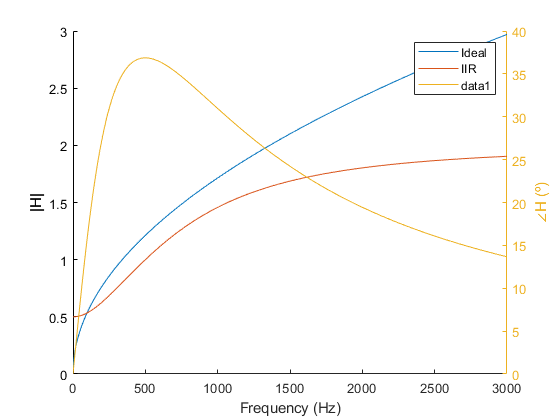

g1 = 4;
g2 = 0.5;
wc = 2*pi*500;
s = 1i*2*pi*f;
H_IIR = g2*(sqrt(g1)/wc*s + 1)./(1/(wc*sqrt(g1))*s + 1);
ax = axes(figure, 'NextPlot', 'Add');
plot(ax, f, abs(H))
plot(ax, f, abs(H_IIR))
ax.XLabel.String = 'Frequency (Hz)';
ax.YLabel.String = '|H|';
legend(ax, 'Ideal', 'IIR')
yyaxis(ax, 'right')
plot(ax, f, rad2deg(angle(H_IIR)))
ax.YLabel.String = '\angle{H} (º)';

Another possibility, more practical, is to use the function iirlpnorm. It allows to provide a custom frequency response. To generate it, we will use Lagrange interpolation. Let's define 3 points: $f_{low} = 100$ Hz, $f_{alias} = 1000$ Hz, $f_{cent} = 500$ Hz. At the same time, we will define three levels for each point. Then, we perform Lagrange interpolation.

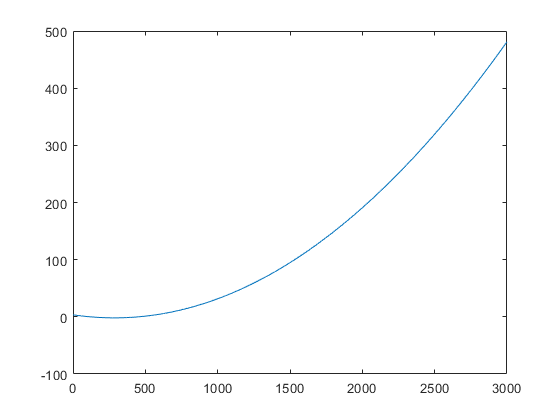

f_low = 100; mag_low = 0.5;
f_alias = 1000; mag_alias = sqrt(1000);
f_center = 500; mag_center = sqrt(f_center/c);
x=[f_low, f_alias, f_center];
xlog = log(x);
y=[mag_low, mag_alias, mag_center];
polynom = LagrangePolynomial( x, y );
values = polyval(polynom, f);

ax = axes(figure);
plot(f, values)